# Fuel Economy Analysis

This demo is an example of performing data mining on historical fuel economy data. We have data from various cars built from year 2000 up to 2012.

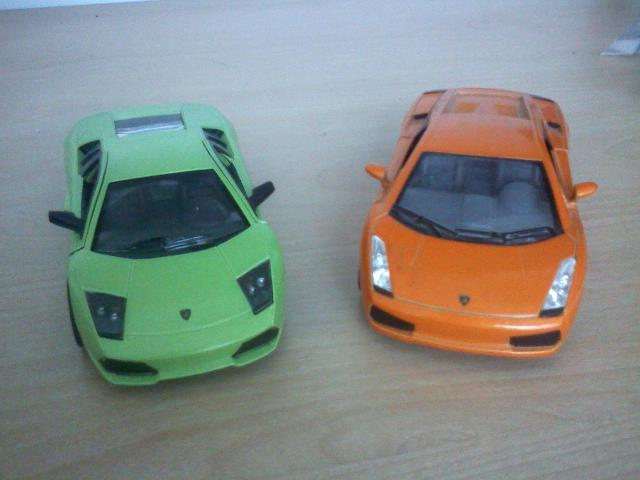

## Import Data into Table

Import from Excel using modified auto-generated function from Import Tool

carData = importfile('2006dat.xlsx');

## Visualize

Plot MPG versus Rated Horsepower

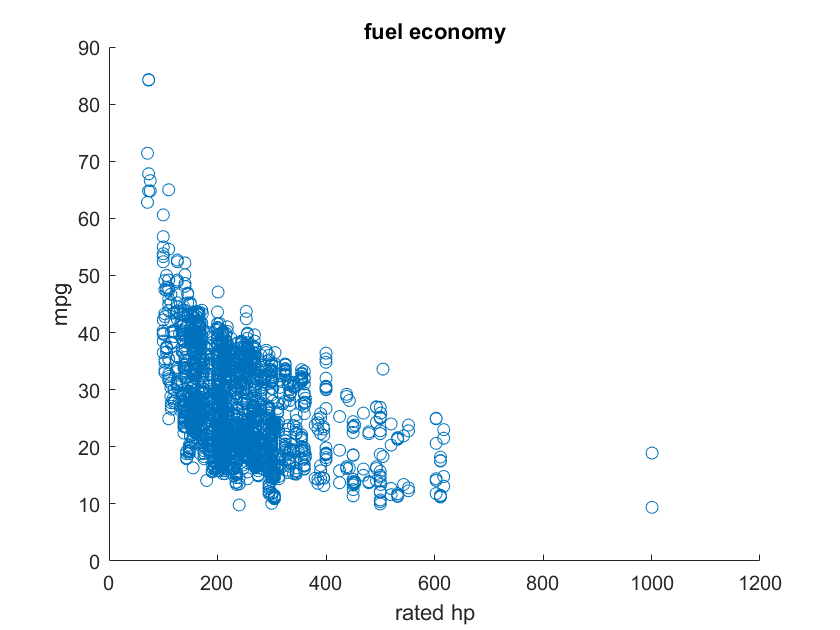

createfigure(carData.RatedHP, carData.MPG);

## Examine Grouping Effects of Categorical Data

In order to extract all "cars":

carIDs = carData.Car_Truck == "car";

In order to extract "city" data for "trucks":

city_truckIDs = (carData.City_Highway == "city" & carData.Car_Truck == "truck");

City versus Highway

cityIDs = carData.City_Highway == "city";
highwayIDs = carData.City_Highway == "highway";

## Grouped Visualizations

Scatter plot by group.

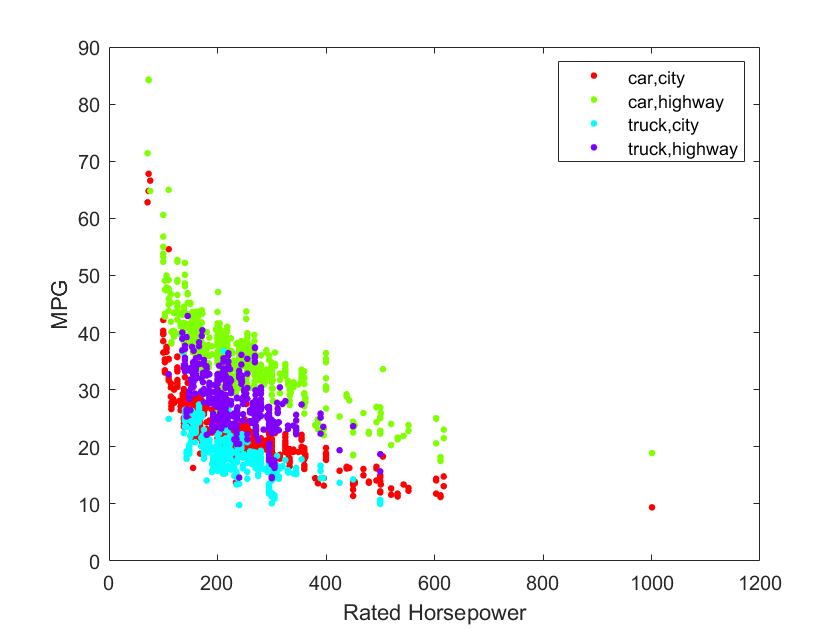

figure
gscatter(carData.RatedHP, carData.MPG, ...
    {carData.Car_Truck, carData.City_Highway}, ...
    '', '.', 10, 'on', 'Rated Horsepower', 'MPG')

## Extract Data for Curve Fitting

Create these variables for Curve Fitting App

RatedHPCity = carData.RatedHP(cityIDs);
MPGCity     = carData.MPG(cityIDs);

% Use the App to develop a curve fit.

## Curve Fitting

Equation:


$$\textrm{MPG}=b_1 +\frac{b_2 }{\textrm{RatedHP}}$$


We can solve this using the Curve Fitting Tool

`cftool(carData.RatedHP, carData.MPG)`

The following is a modified version of the auto-generated m-file from `cftool`.

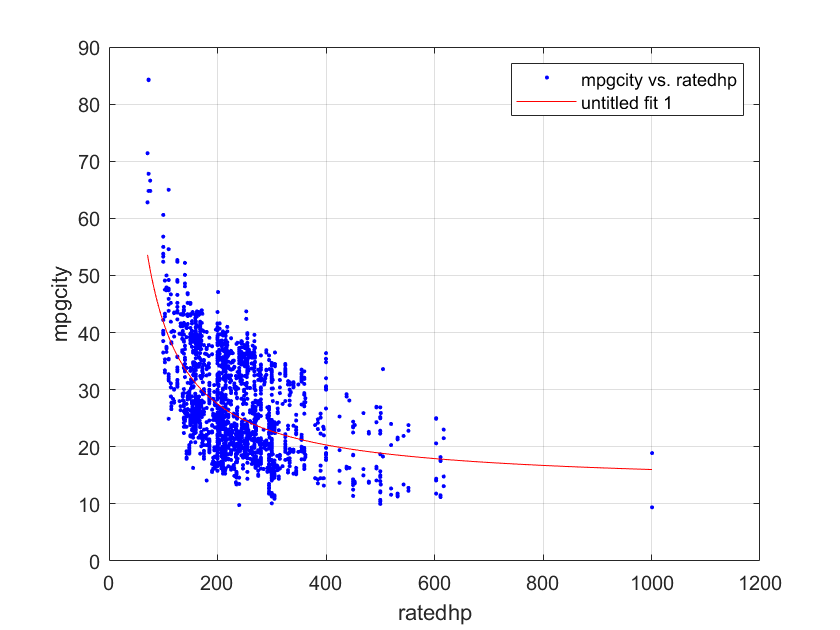

cf = createFit(carData.RatedHP, carData.MPG);

## Plot Data and Model

The result from the Curve Fitting Toolbox has a `plot` method for displaying the result graphically. We can choose to display the prediction bounds for the fit.

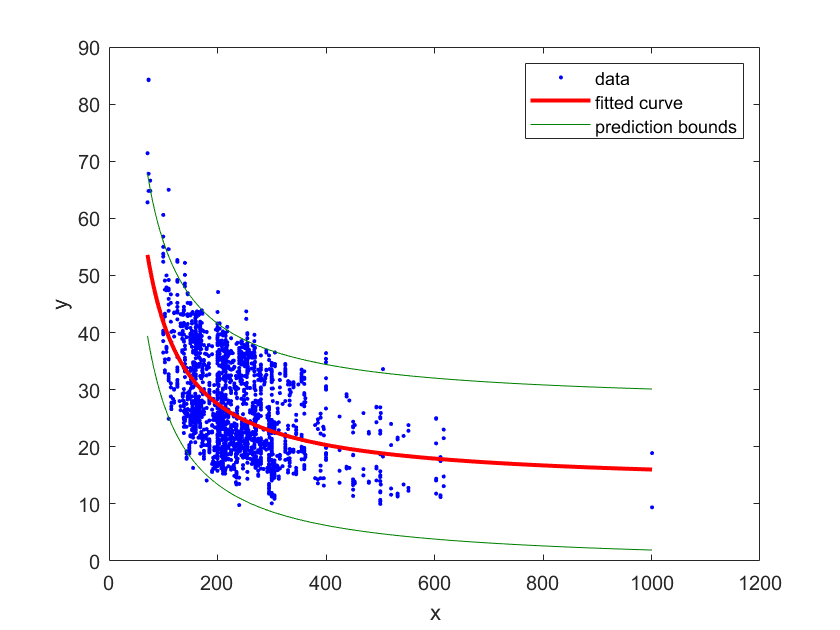

figure
hh = plot(cf, 'r', carData.RatedHP, carData.MPG, 'predobs', 0.95);
hh(2).LineWidth = 2;
for ii = [3 4]
    hh(ii).LineStyle = '-';
    hh(ii).Color = [0 0.5 0];
end

## Plot of Data and Model (for different groups)

We will apply the similar modeling technique to the data for different combinations of groups (Car-Truck and City-Highway)

Model different combinations:

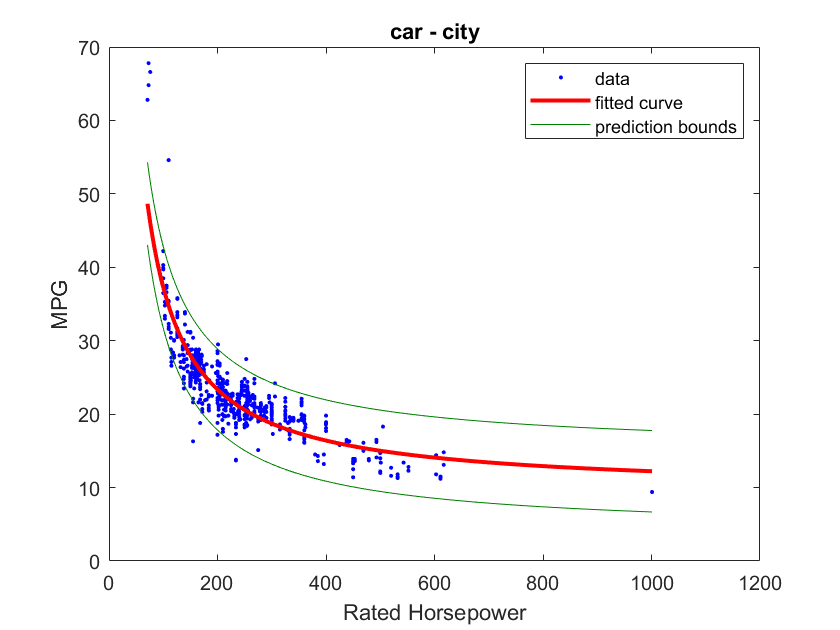

mdl =      Linear model:
     mdl(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       9.443  (8.874, 10.01)
       b =        2784  (2675, 2894)

gof = struct with fields:
           sse: 5.7126e+03
       rsquare: 0.7763
           dfe: 721
    adjrsquare: 0.7760
          rmse: 2.8148


[mdl,gof] = modelMPG(carData, 'car', 'city')

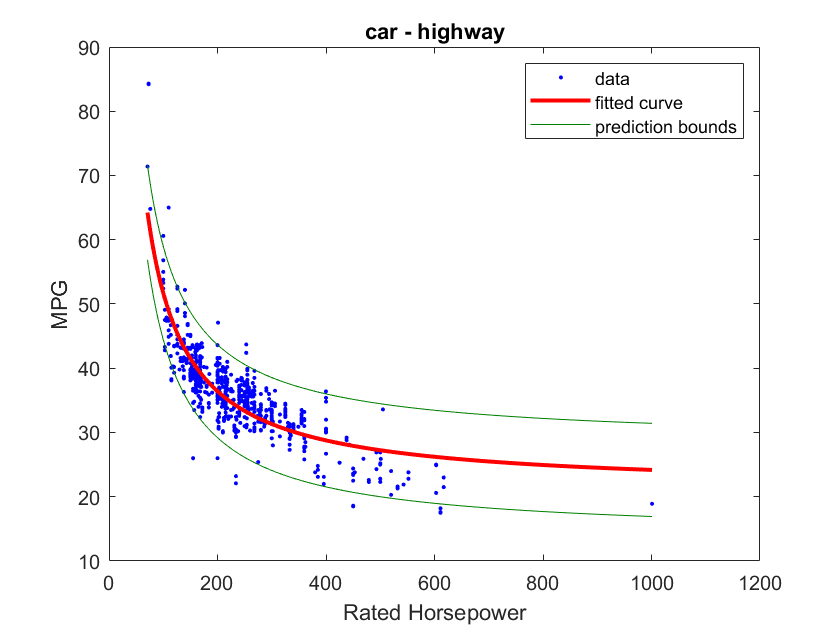

mdl =      Linear model:
     mdl(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       21.12  (20.37, 21.86)
       b =        3061  (2918, 3205)

gof = struct with fields:
           sse: 9.6775e+03
       rsquare: 0.7108
           dfe: 715
    adjrsquare: 0.7104
          rmse: 3.6790


[mdl,gof] = modelMPG(carData, 'car', 'highway')

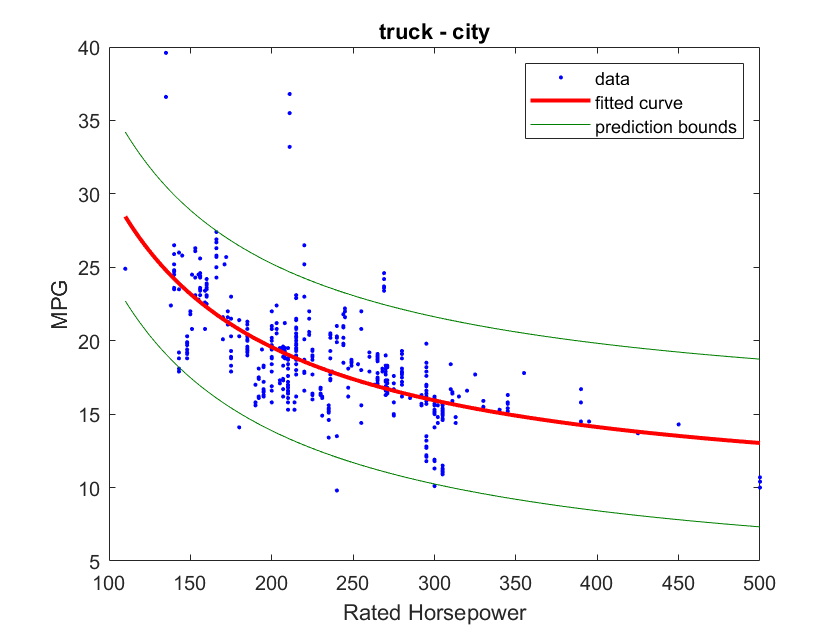

mdl =      Linear model:
     mdl(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       8.685  (7.729, 9.641)
       b =        2175  (1977, 2373)

gof = struct with fields:
           sse: 4.4074e+03
       rsquare: 0.4689
           dfe: 527
    adjrsquare: 0.4679
          rmse: 2.8919


[mdl,gof] = modelMPG(carData, 'truck', 'city')

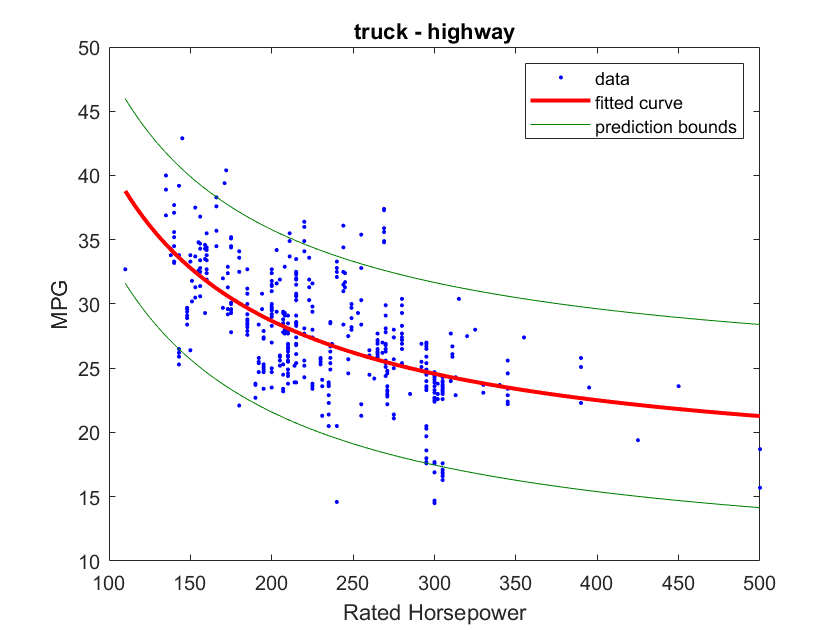

mdl =      Linear model:
     mdl(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       16.34  (15.13, 17.54)
       b =        2471  (2221, 2721)

gof = struct with fields:
           sse: 6.8494e+03
       rsquare: 0.4176
           dfe: 526
    adjrsquare: 0.4165
          rmse: 3.6086


[mdl,gof] = modelMPG(carData, 'truck', 'highway')

*Copyright 2017 The MathWorks, Inc.*